clc
clear
close all


%Serena Elijah
%AE 426 Project 2

syms phi theta psi wp_dot ws_dot wn_dot wp_ddot ws_ddot wn_ddot A B C ws wn wp m g d 

%phi is the first angle of rotation
%theta is the second angle of rotation 
%psi is the third angle of rotation

m = 3 ; %kg
rI = 3/100 ; %m
g = 9.81 ; %m/s^2
d = 5/100 ; %m d=h

%phi = 0; theta = 0.01; psi = 0 ; wp = 0 ;  wn = 0; ws= 50 ;
%r0 = [phi theta psi wp wn ws] ; %initial conditions

r0 = [ 0 0.051 0 0 0 50] ; %Initial condition
tspan = 0:0.1:4.5 ; %time span 

%INERTIA 

A  = (3/10)*m*(rI^2) 

A = 8.1000e-04

C = (3/10)*m*(rI^2 + 4*d^2) 

C = 0.0098

%Ode45 to solve differential equation using initial conditions
options = odeset('RelTol', 1e-9, 'AbsTol', 1e-9) ;
[t,r] = ode45(@(t,r) eom(t, r), tspan, r0, options) ;


Plots

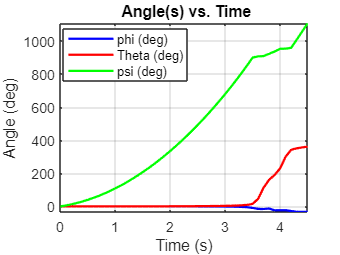


%% Plotting Results

% Plot for r(1) vs t (phi)
figure;

plot(t, r(:, 1), 'b', 'LineWidth', 1.5);
hold on;
plot(t, r(:, 2), 'r', 'LineWidth', 1.5)
hold on;
plot(t, r(:, 3), 'g', 'LineWidth', 1.5);

legend('phi (deg)', 'Theta (deg)', 'psi (deg)', 'Location', 'best')

title(' Angle(s) vs. Time');
xlabel('Time (s)');
ylabel('Angle (deg)');
grid on;

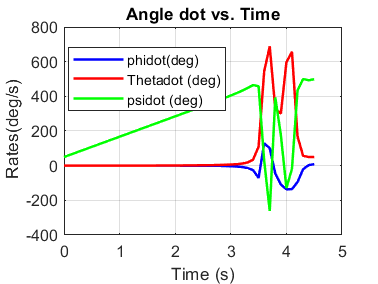




figure;

plot(t, r(:, 4), 'b', 'LineWidth', 1.5);
hold on;
plot(t, r(:, 5), 'r', 'LineWidth', 1.5);
hold on;
plot(t, r(:, 6), 'g', 'LineWidth', 1.5);
title('Angle dot vs. Time');
xlabel('Time (s)');
ylabel(' Rates(deg/s)');
legend('phidot(deg)', 'Thetadot (deg)', 'psidot (deg)', 'Location', 'best')

grid on;

Functions eom

function drdt = eom(t,r) 

m = 3 ; %kg
rI = 3/100 ; %m
g = 9.81 ; %m/s^2
d = 5/100 ; %m d=h
C  = (3/10)*m*(rI^2) ;
A = (3/10)*m*(rI^2 + 4*d^2) ;
Mf = -0.095;



%drdt = [wp wn ws wp_dot wn_dot ws_dot]

drdt(1) = r(4) ;

drdt(2) = r(5)  ;

drdt(3) = r(6) ;

drdt(4) = (1/A*sind(r(2)))*( (-A*r(4)*r(5)*cosd(r(2))) + (-C*r(6)*r(5)) + ((A-C)*r(4)*r(5)*cosd(r(2))) ) ;

drdt(5) = (1/A)*((m*g*d*sind(r(2))) + (-C*r(4)*r(6) *sind(r(2))) + (-(C-A)*r(4)^2*cosd(r(2))*sind(r(2)))); %wn_dot

drdt(6) = -(Mf/C)  -(drdt(4)*cosd(r(2))) + r(4)*r(5)*sind(r(2)); %ws_dot

drdt = drdt' ;


end
